tx_bs=rand(1,1280)>0.5; % generate sequence of 1280 random bits
SPBlist = 1:15; % list of bit times to test

num_SPB = length(SPBlist); % number of bit times to test
BERlist = zeros(1,num_SPB); % initialize bit error rate array

for i = 1:num_SPB %generate the SPB list
    SPB = SPBlist(i);
    tx_wave = format_bitseq(tx_bs,SPB); % create waveform following protocol
    
    % channel %
    ch = Channel;
    ch.distance = 10;  
    rx_wave = txrx(ch,tx_wave); % transmit waveform through channel
   
    rx_bs = waveform2bitseq(rx_wave,SPB,ch); % decode received waveform
    BERlist(i) = compute_BER(tx_bs,rx_bs); % compute the BER
end

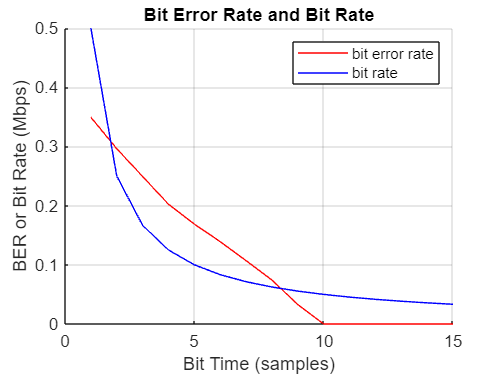

h = figure();
% Add code below that
% 1. computes bit rate in Mbps (mega-bits per second) for each bit time in SPBList assuming 
%    Fs = 500 kHz
% 2. plots the BER and the bit rate versus bit time in samples on the same
%    graph

Fs = 500e3;
bitratelist = (Fs*ones(1,length(SPBlist))./ SPBlist)*1e-6;  % bitrate(in MHz/s) = Fs / SPB
hold on;
plot(SPBlist, BERlist, "r");
plot(SPBlist, bitratelist, "b");


% code to label plot -- do not modify
title('Bit Error Rate and Bit Rate');
xlabel('Bit Time (samples)');
ylabel('BER or Bit Rate (Mbps)');
legend('bit error rate','bit rate');
grid on;